# Modelowanie i symulacja w programie MATLAB cz.2

## Jan Rosa 410269 AiR

## Zad 1

### Zad a

 Utwórz m-skrypt wczytujący dane z pliku daneP.csv a następnie realizującego wizualizację danych na wykresie typu plot (każda zmienna na osobnym wykresie). Dodaj do każdego wykresu osobny tytuł. - Wskazówka: użyj import wizarda do importu danych, następnie wygeneruj m-funkcję do importu danych i wykorzystaj ją w swoim m-skrypcie

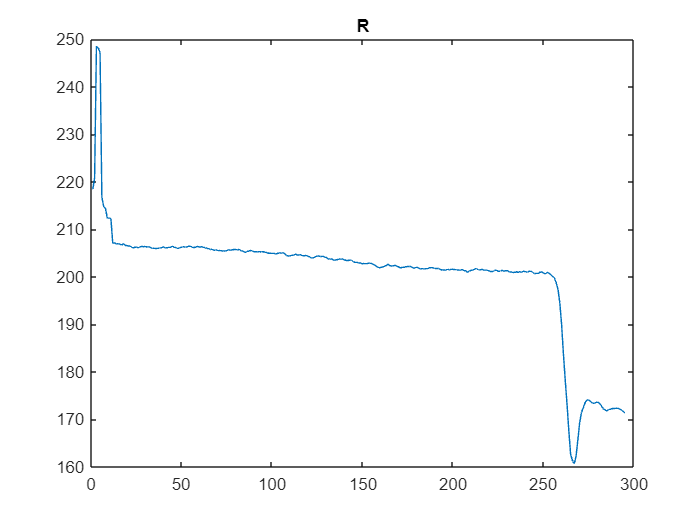

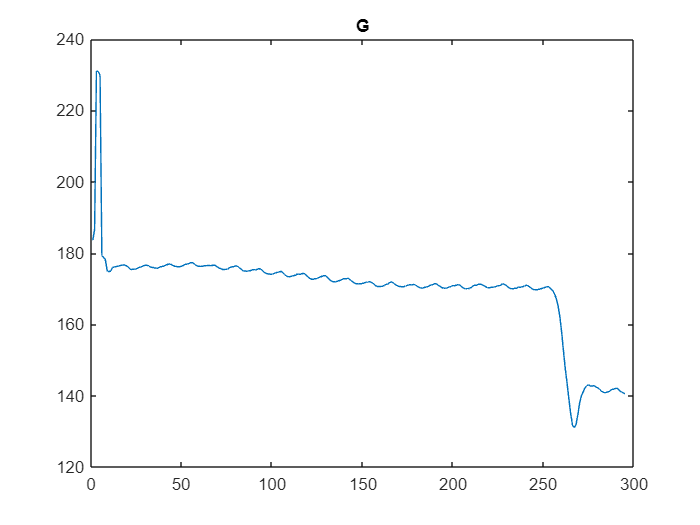

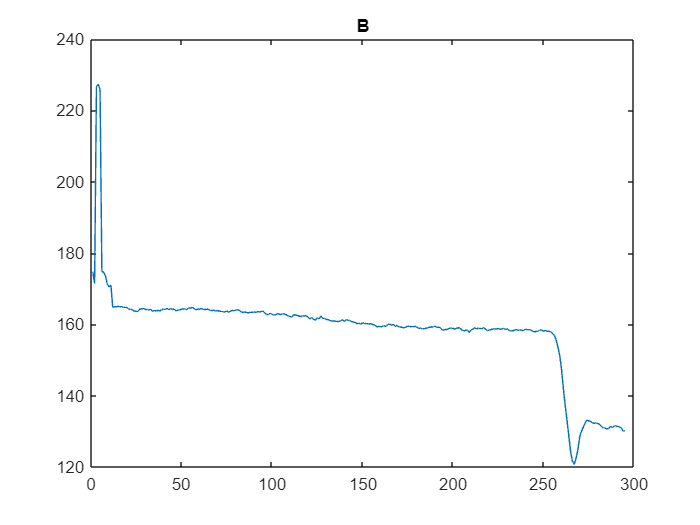

import1

Kod m-skryptu:

daneP = readmatrix('daneP.csv');

R = daneP(:, 1);

G = daneP(:, 2);

B = daneP(:, 3);

figure

subplot(1, 3, 1)

plot(R)

title("R")

subplot(1, 3, 2)

plot(G)

title("G")

subplot(1, 3, 3)

plot(B)

title("B")

### Zad b

Z zaimportowanych danych wybierz taki fragment, na którym widoczny jest sygnał okresowy. Utwórz nową zmienną zawierającą wybrany fragment sygnału i zwizualizuj ją na osobnym oknie wykresu. - Wskazówka: Przyglądnij się wykresowi każdej składowej i wybierz taką, na której okresowość jest najlepiej widoczna. Następnie, przy pomocy indeksowania, wybierz fragment pomijając zakłócenia na początku i na końcu sygnału.

okres = daneP(100:230,:)

okres =   204.9200  174.0600  162.8000
  204.9200  174.2500  162.6100
  204.7800  174.4000  162.6900
  204.8800  174.6200  162.9900
  205.0600  174.6600  162.8400
  204.9700  174.8800  162.7600
  205.0600  174.5200  162.9800
  204.8600  173.9700  162.8400
  204.4700  173.5600  162.6800
  204.3800  173.3500  162.3200


len = 1:131

len =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


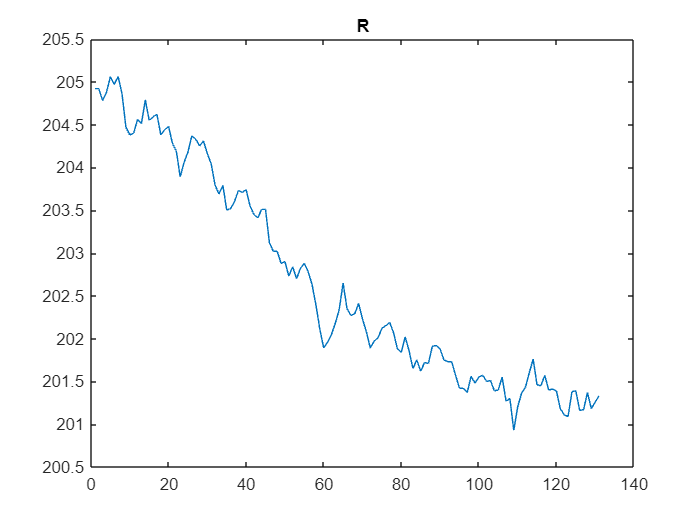

figure("Name","R")
plot(okres(:, 1))
title("R")

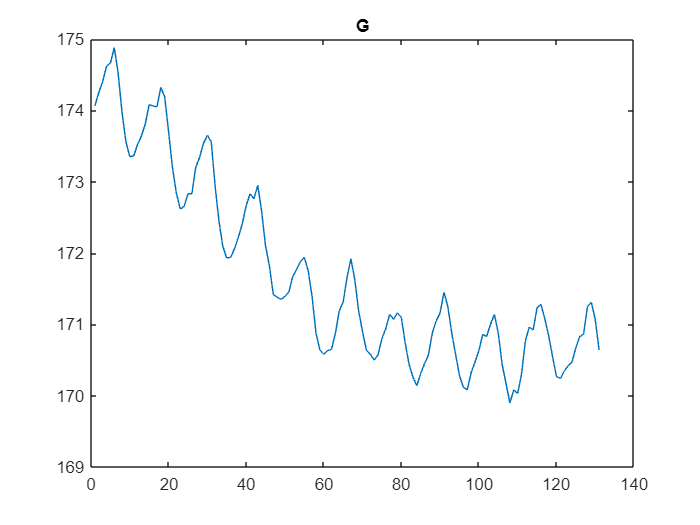

figure("Name","G")
plot(okres(:, 2))
title("G")

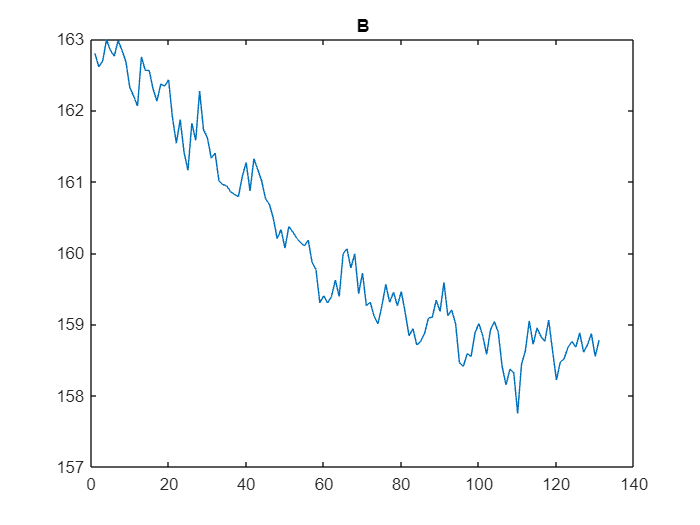

figure("Name","B")
plot(okres(:, 3))
title("B")

### Zad c

Z wybranego fragmentu sygnału, usuń trend poprzez dopasowanie krzywej wielomianowej. Dobierz stopień wielomianu jak najmniejszego stopnia przy zachowaniu jak najmniejszego błędu dopasowania (funkcja norm). Do wykresu z poprzedniego punktu dodaj linię dopasowanego trendu (inny kolor). Utwórz nowy wykres zawierający sygnał z usuniętym trendem. - Wskazówka – możesz zrealizować dopasowanie przy pomocy narzędzia Basic Fitting Tool, a następnie wygenerować m-kod i wybrać z niego potrzebne fragmenty analizy sygnału

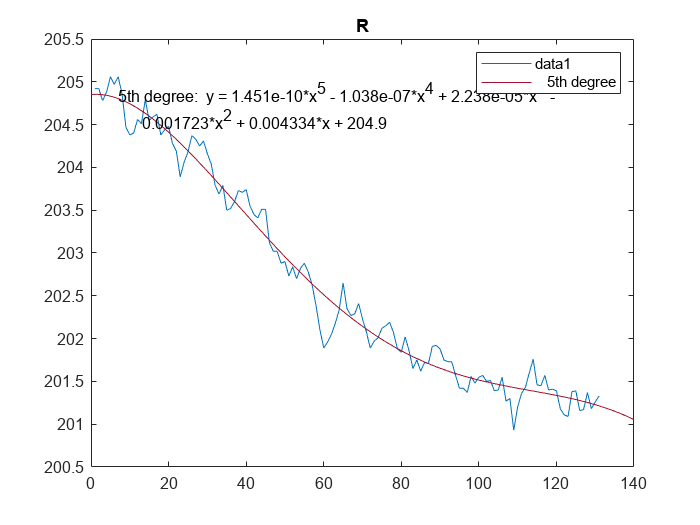

figure
R_createfigure(okres(:, 1))

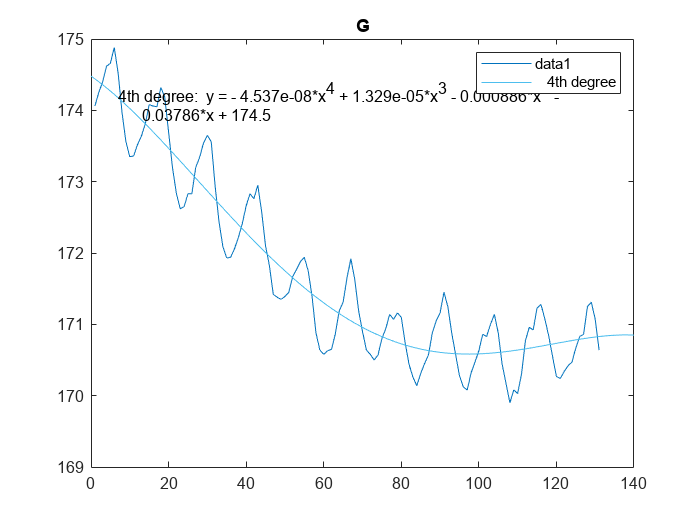

figure
G_createfigure(okres(:, 2))

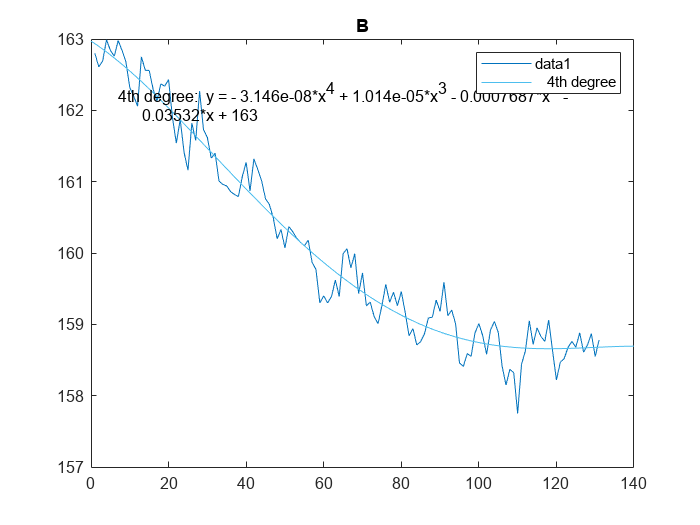

figure
B_createfigure(okres(:, 3))

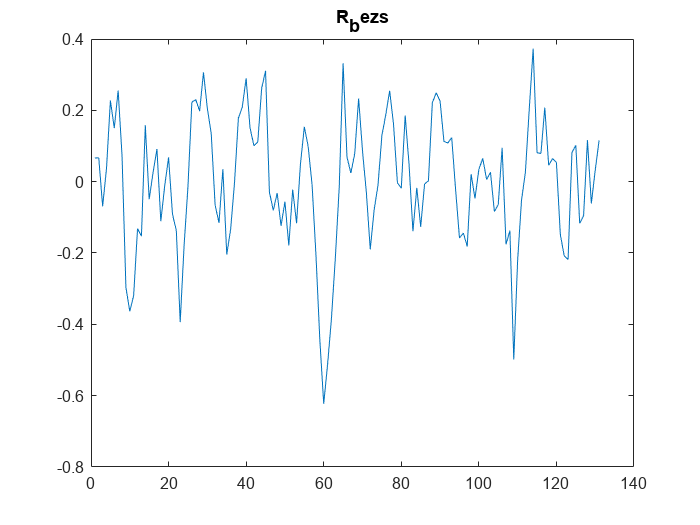

R_szum = polyval(polyfit(len, okres(:, 1), 5), len)';
G_szum = polyval(polyfit(len, okres(:, 2), 4), len)';
B_szum = polyval(polyfit(len, okres(:, 3), 2), len)';

%figure("Name","R poly")
%plot(R_szum)
%title("R poly")
%figure("Name","G poly")
%plot(G_szum)
%title("G poly")
%figure("Name","B poly")
%plot(B_szum)
%title("B poly")
R_bezs = okres(:,1) - R_szum;
G_bezs = okres(:,2) - G_szum;
B_bezs = okres(:,3) - B_szum;

figure
plot(R_bezs)
title("R_bezs")

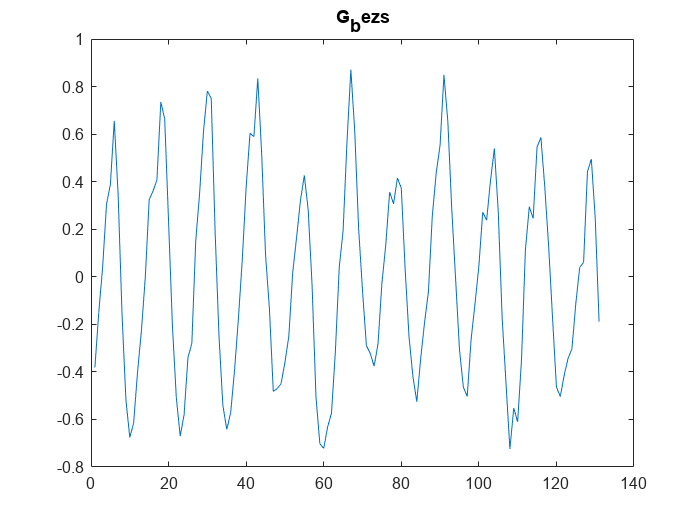

figure
plot(G_bezs)
title("G_bezs")

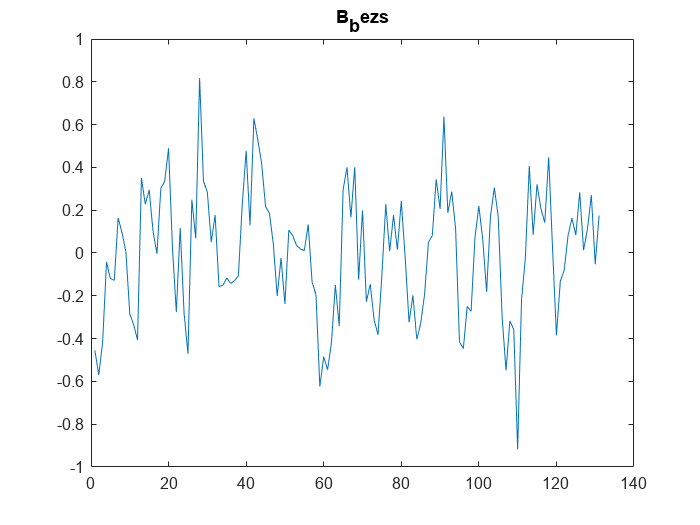

figure
plot(B_bezs)
title("B_bezs")

Zad d

Znajdź częstotliwość charakterystyczną sygnału. Sformatuj wykres dodając do niego w sposób programowy: opisy osi x,y i tytuł wykresu. Dodaj do wykresu punkt w miejscu maksimum (częstotliwość charakterystyczna) oraz opis informujący o wartości częstotliwości tego maksimum. - Wskazówka: użyj funkcji fft (patrz przykład w dokumentacji) z częstotliwością próbkowania odczytaną z pliku daneP.csv - Aby dodać do wykresu opis wykorzystaj funkcję text oraz sformatuj tekst przy pomocy funkcji sprintf.

R_fft = abs(fft(R_bezs))

R_fft =     0.0000
    0.0888
    2.3502
    5.5513
    1.8153
    1.2325
    4.3104
    0.8612
    2.0382
    3.4866


G_fft = abs(fft(G_bezs))

G_fft =     0.0000
    0.3351
    3.6538
    3.2213
    1.8906
    3.9866
    6.1062
    2.7604
    4.7416
   10.3578


B_fft = abs(fft(B_bezs))

B_fft =     0.0000
    4.2747
    4.1410
    4.2059
    2.5028
    8.0209
    2.3161
    2.0230
    0.8341
    4.8043


len/2

ans =     0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000   25.0000


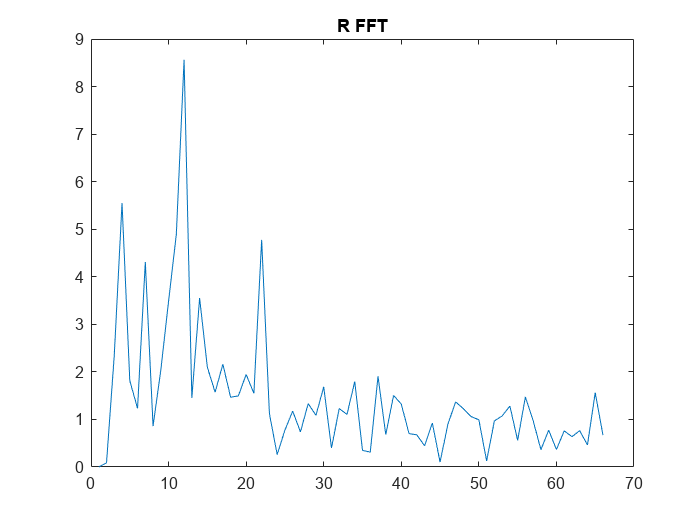

figure
plot(R_fft(1:66))
title("R FFT")

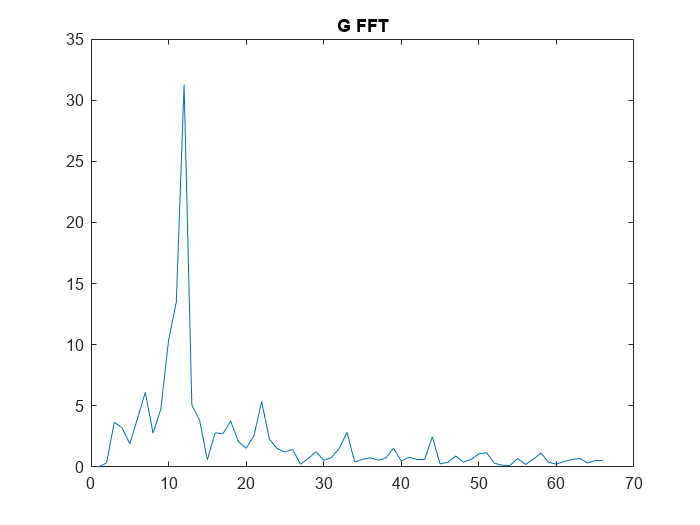

figure
plot(G_fft(1:66))
title("G FFT")

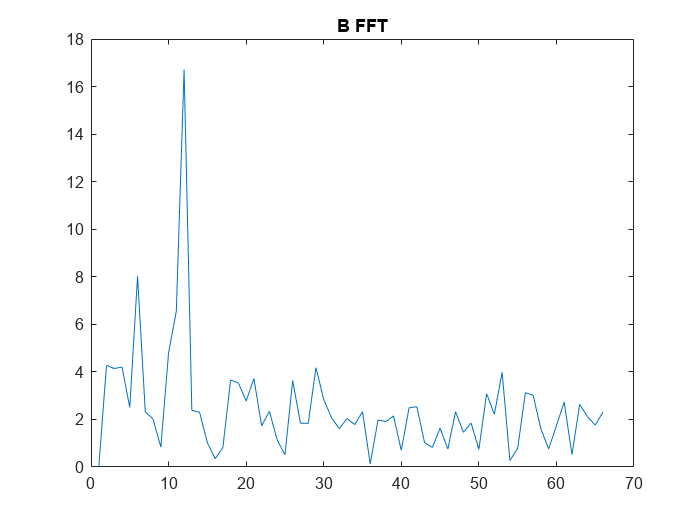

figure
plot(B_fft(1:66))
title("B FFT")

Zad e

Uzupełnij m-plik o komentarze i dokumentacje. Wygeneruj raport w formacie HTML

## Zad 2

Zad a

Przy pomocy polecenia randn wygeneruj tablicę 3x3 liczb pseudolosowych R o rozkładzie normalnym (średnia 0 i odchylenie standardowe). Następnie utwórz zmienną A jako typ UINT32, zawierającą liczbę 100. Pomnóż zmienną R przez A, odpowiednio dostosowując typy danych. Rezultat (zmienna B) powinna być typu UINT32. Zwróć uwagę czy rezultaty mnożenia są poprawne ! W sprawozdaniu zanotuj liczbę bajtów potrzebną do zapamiętania jednej liczby typu double oraz jednej liczby typu UINT32 (wskazówka – skorzystaj z polecenie whos).

R = normrnd(0, 1, 3, 3)

R =    -1.9609    2.9080   -1.0582
   -0.1977    0.8252   -0.4686
   -1.2078    1.3790   -0.2725


A = uint32(100)

A = uint32
100

B = uint32(R * double(A))

B = 3×3 uint32 matrix
     0   291     0
     0    83     0
     0   138     0


double zawiera 8 bajtów

uint32 zawiera 4 bajty

Zad b

Utwórz dwie tablice znakowe zawierające teksty: „ćwiczenie 2” oraz „laboratorium 1”. Połącz te dwie tablice (wskazówka – skorzystaj z polecenia strvcat)

Zad c

Utwórz tablicę znakową str1 zawierającą tekst „Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud”. Znajdź indeksy słów zaczynających się na literę „b”, kończących na literę „d” i nie zawierających litery „u”. Wskazówka – skorzystaj z wyrażeń regularnych – dokumentacja do polecenia regexp

Zad d

Utwórz tablicę komórkową o rozmiarze 2x2 zawierającą następujące dane jak na rysunku poniżej. Wybierz z tablicy komórkowej, tablicę liczb pseudolosowych znajdującą się w komórce 2-wiersz, 1- kolumna, dodaj do niej wartość 100, a rezultat zapisz w to samo miejsce do tablicy komórkowej. 

Zad e

Oblicz całkę oznaczoną w przedziale 𝑥 ∈ (−2,2) z funkcji 𝑓(𝑥) = 𝑥 2 − 2 ∙ 𝑥 + 4 i narysuj jej wykres dla tego przedziału. Wskazówka – zdefiniuj funkcję przy pomocy uchwytu do funkcji, wykorzystaj funkcję quad oraz fplot.

f = @(x) x.^2 - 2.*x + 4

f = function_handle with value:
    @(x)x.^2-2.*x+4


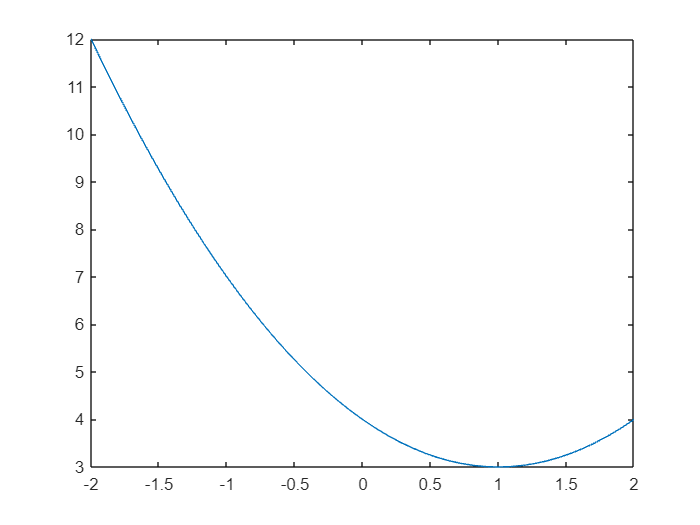

fplot(f, [-2, 2])

integral(f, -2, 2)

ans = 21.3333

Zad f

Utwórz typ danych tabelaryczny (table) zawierający dane jak na rysunku poniżej. Wyeksportuj dane z tabeli do pliku CSV. Wskazówka – sprawdź w systemie pomocy jak definiować nazwy kolumn oraz wierszy. Liczby do tabeli wygeneruj losowo. Skorzystaj z polecenia writetable